# **S&S Project**

## Semester Project EE-232 

## Design and Implementation of a 5-band Graphic Equalizer 

### Part 1:

The goal of this project is to design a 10-band graphic equalizer and then to implement it - first employing Simulink to check the design and then designing a GUI. 

Matlab can be employed to design the required filters an-+d then Simulink can be used  to implement the graphic equalizer in real time. Most commercial equalizers use either  1/3 octave or 2/3 octave bandpass filters but to keep this from becoming too large we will employ one octave bandpass filters. Following are the design specifications for the  equalizer:

- Employing Matlab, design 5 different bandpass filters with center frequencies of  63 Hz, 250 Hz, 1000 Hz, 4000 Hz, and 16000 Hz. These center frequencies  correspond to the ISO (International Standards Organization) standard for graphic  equalizer center frequencies.

- The bandwidth of each filter is the frequency difference ∆f = f2 – f1, where f1 and  f2 correspond to the frequencies where the gain is 3 dB less than the maximum  gain at the center frequency. It also is necessary to choose f1 and f2 such that the  center frequency, fc, is equal to the geometric mean of f1 and f2, i.e. fc = (f1f2) 1/2 .  We also have to choose the bandwidth of each filter so that we get a flat frequency  response when all filter gains are equal and added together.

- You can use Butterworth filters; however you are free to choose the order of the  filters. The Matlab help file for the Butterworth filter is the following:                                                                                                                                         ***[B,A] = butter(N,Wn) designs an Nth order lowpass digital Butterworth filter and returns the filter  coefficients in length N+1 vectors B (numerator) and A (denominator). The coefficients are listed  in descending powers of z. The cutoff frequency Wn must be 0.0 < Wn < 1.0, with 1.0 corresponding  to half the sample rate.                                                                                                                                         If Wn is a two-­­element vector, Wn = [W1 W2], butter returns an order 2N bandpass filter with  passband W1 < W < W2.                                                                                                                                                                                     [B,A] = butter(N,Wn,'high') designs a highpass  filter. [B,A] = butter(N,Wn,'low') designs a lowpass  filter. [B,A] = butter(N,Wn,'stop') is a bandstop filter if Wn = [W1 W2]***

- Write a Matlab m-file to compute the set of filter coefficients and plot the  combination (sum) of all filter frequency responses. Note that you can use the  ‘freqz’ command to easily find the frequency response of a filter defined by the  filter coefficient arrays B and A. Your goal is to achieve as flat of a frequency  response as you can when all the frequency response of all filters are added ± 1  dB is a good goal. Remember that the center frequency of each filter must be fixed  to one of the five values given above and the upper and lower cutoff frequencies  f2 & f1 must satisfy fc = (f1f2) 1/2 . Your goal is to find the ∆f value for each filter that achieves a flat frequency response when all filters are  combined with equal weights. [Hint: the filters should all be constant Q, where  Q = fc / (f2 – f1), so once you find the right value for Q all filters should have the  same Q.]                                                                     The simplified 3-band graphic equalizer is shown below, where the filters are in  parallel and each one is followed by a gain (using the Matlab slider gain block).  Your mixer will have 5 filters in parallel.                                                                                                                         We would like to be able to adjust the gain of each band by ± 12 dB. Remember that 6dB corresponds to approximately a factor of 2x, so 12 dB is about 4x. So +12 dB is like multiplying by 4 and -12 dB is like multiplying by ¼.Use these values as  the limits for the slider gain blocks. One final note: The “From Multimedia File” and “To Audio Device” blocks can be  found in the DSP Toolbox

### Part 2:

Design a GUI with the following provisions:

-  A ‘load’ button that can load an audio file of your choice (Suggestion: choose a  file with large frequency range e.g a symphony). 

- Display for the input and output signals. 

- Display for the input and output spectrum. 

- Adjustable gain sliders for the filters. 

- A ‘play’ button that can playback the output file.

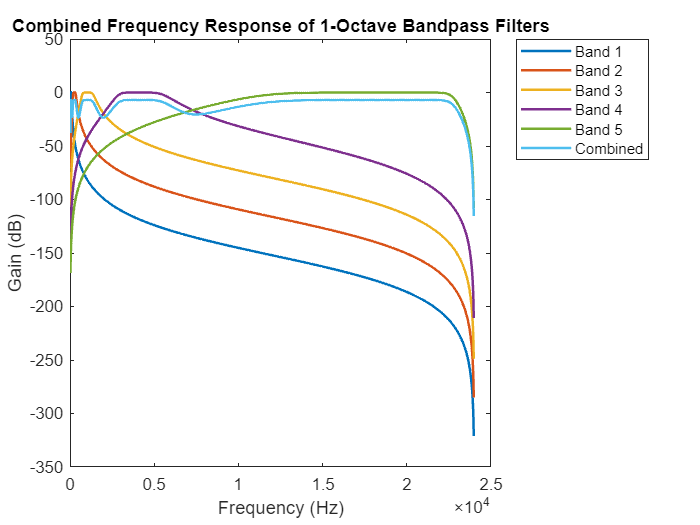

% Define center frequencies (Hz)
center_frequencies = [63, 250, 1000, 4000, 16000];

% Define Q factor
Q = sqrt(2);

% Define sampling frequency (Fs)
Fs = 48000;

% Preallocate arrays for filter coefficients
B = cell(1, length(center_frequencies));
A = cell(1, length(center_frequencies));

% Design octave bandpass filters for each center frequency
for i = 1:length(center_frequencies)
    fc = center_frequencies(i);
    
    % Calculate lower and upper cutoff frequencies for octave bandpass filter
    f1 = fc / Q;
    f2 = 2 * f1;

    % Design Butterworth bandpass filter with Q factor
    [B{i}, A{i}] = butter(3, [f1, f2]/(Fs/2), 'bandpass'); 
end

% Plot individual frequency responses of all bands
figure;
for i = 1:length(center_frequencies)
    [H, F] = freqz(B{i}, A{i}, 1024, Fs);
    plot(F, 20*log10(abs(H)), 'LineWidth', 1.5);
    hold on;
end

% Plot the combined frequency response of all filters
combined_response = zeros(1024, 1);
for i = 1:length(center_frequencies)
    [H, F] = freqz(B{i}, A{i}, 1024, Fs);
    combined_response = combined_response + abs(H).^2; % Accumulate squared magnitude
end

% Normalize the combined response
combined_response = 20*log10(sqrt(combined_response/length(center_frequencies)));

% Plot the normalized combined response
plot(F, combined_response, 'LineWidth', 1.5);

title('Combined Frequency Response of 1-Octave Bandpass Filters');
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
legend('Band 1', 'Band 2', 'Band 3', 'Band 4', 'Band 5', 'Combined', 'Location', 'northeastoutside');
hold off;

%grid on;
% Display additional filter information
fprintf('Filter Information:\n');

Filter Information:


for i = 1:length(center_frequencies)
    f1 = center_frequencies(i) / Q;
    f2 = 2 * f1;
    
    fprintf('Band %d - Center Frequency: %d Hz, Lower Frequency: %.2f Hz, Upper Frequency: %.2f Hz, Bandwidth: %.2f Hz\n', i, center_frequencies(i), f1, f2, f2-f1);
end

Band 1 - Center Frequency: 63 Hz, Lower Frequency: 44.55 Hz, Upper Frequency: 89.10 Hz, Bandwidth: 44.55 Hz
Band 2 - Center Frequency: 250 Hz, Lower Frequency: 176.78 Hz, Upper Frequency: 353.55 Hz, Bandwidth: 176.78 Hz
Band 3 - Center Frequency: 1000 Hz, Lower Frequency: 707.11 Hz, Upper Frequency: 1414.21 Hz, Bandwidth: 707.11 Hz
Band 4 - Center Frequency: 4000 Hz, Lower Frequency: 2828.43 Hz, Upper Frequency: 5656.85 Hz, Bandwidth: 2828.43 Hz
Band 5 - Center Frequency: 16000 Hz, Lower Frequency: 11313.71 Hz, Upper Frequency: 22627.42 Hz, Bandwidth: 11313.71 Hz
